# MUSI 6202: Final Denoising Project

## Baseline System Overview

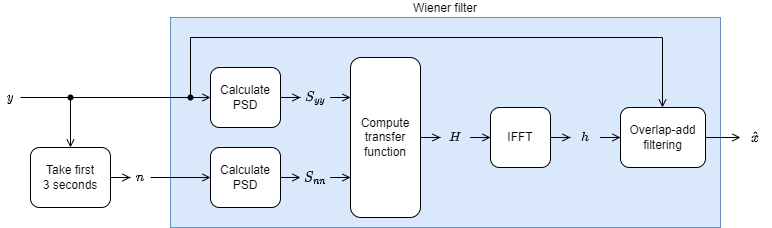

The baseline system is a simple Wiener filter with the noise profile drawing from the first 3 seconds of the noisy signal. The Wiener transfer function were computed in frequency domain from the estimated power spectral densities, then converted back to the time domain. The final filtering was done in the time-domain using overlap-add filtering.

## Our System Overview 

For more information, please check the documentation file in "doc" folder.

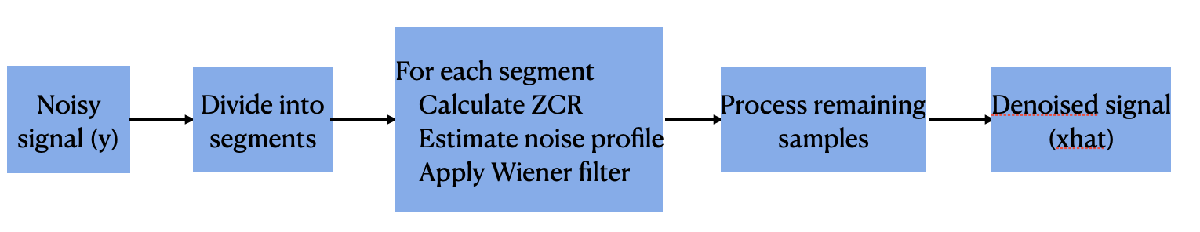

The denoise function is a MATLAB implementation for denoising an input audio signal by estimating its noise profile and applying a time-vary Wiener filter. The function divides the input signal into segments, calculates the Zero Crossing Rate (ZCR) for each segment, and finds the maximum ZCR value to estimate the noise profile. Then, it applies the Wiener filter to each segment using the estimated noise profile and concatenates the filtered segments to form the denoised output signal.

### Matlab Toolbox

Voicebox (http://www.ee.ic.ac.uk/hp/staff/dmb/voicebox/voicebox.html)

### Contribution

- Jiaying: implement the spectral subtraction method, write the documentation;

- Joy: implement the time-varying Wiener filter method, write the comments;

- Sawyer: fix the grammar and typo in the documentation and read through the code.

addpath(genpath("./src"));

## Evaluation on the development set

devDataPath = './data/dev';

devDataFolders = dir(devDataPath);
devDataFolders = devDataFolders(3:end);

nDevSamples = size(devDataFolders, 1);

initSnr = NaN(nDevSamples, 1);
finalSnr1 = NaN(nDevSamples, 1);
finalSnr2 = NaN(nDevSamples, 1);

for i = 1:nDevSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i).name, "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i).name, "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);

    estimSig1 = denoise1(noisySig, fs);
    estimSig2 = denoise(noisySig, fs);
    
    initSnr(i) = computeSnr(cleanSig, noisySig);
    finalSnr1(i) = computeSnr(cleanSig, estimSig1);   
    finalSnr2(i) = computeSnr(cleanSig, estimSig2); 
end

deltaSnr1 = finalSnr1 - initSnr;
deltaSnr2 = finalSnr2 - initSnr;

### Result statistics

fprintf("Input SNR (dB)");

Input SNR (dB)

descStats(initSnr);

min    	median 	mean   	max    	std    
-11.90	1.54	0.43	10.92	6.71



fprintf("Output SNR (dB)");

Output SNR (dB)

descStats(finalSnr1);

min    	median 	mean   	max    	std    
-11.79	3.12	2.98	11.39	4.25


descStats(finalSnr2);

min    	median 	mean   	max    	std    
-11.79	3.24	2.70	11.50	4.89


fprintf("Change in SNR (dB)");

Change in SNR (dB)

descStats(deltaSnr1);

min    	median 	mean   	max    	std    
-5.06	2.05	2.55	11.90	3.37


descStats(deltaSnr2);

min    	median 	mean   	max    	std    
-4.87	1.68	2.27	11.27	3.01


### Visualizing results

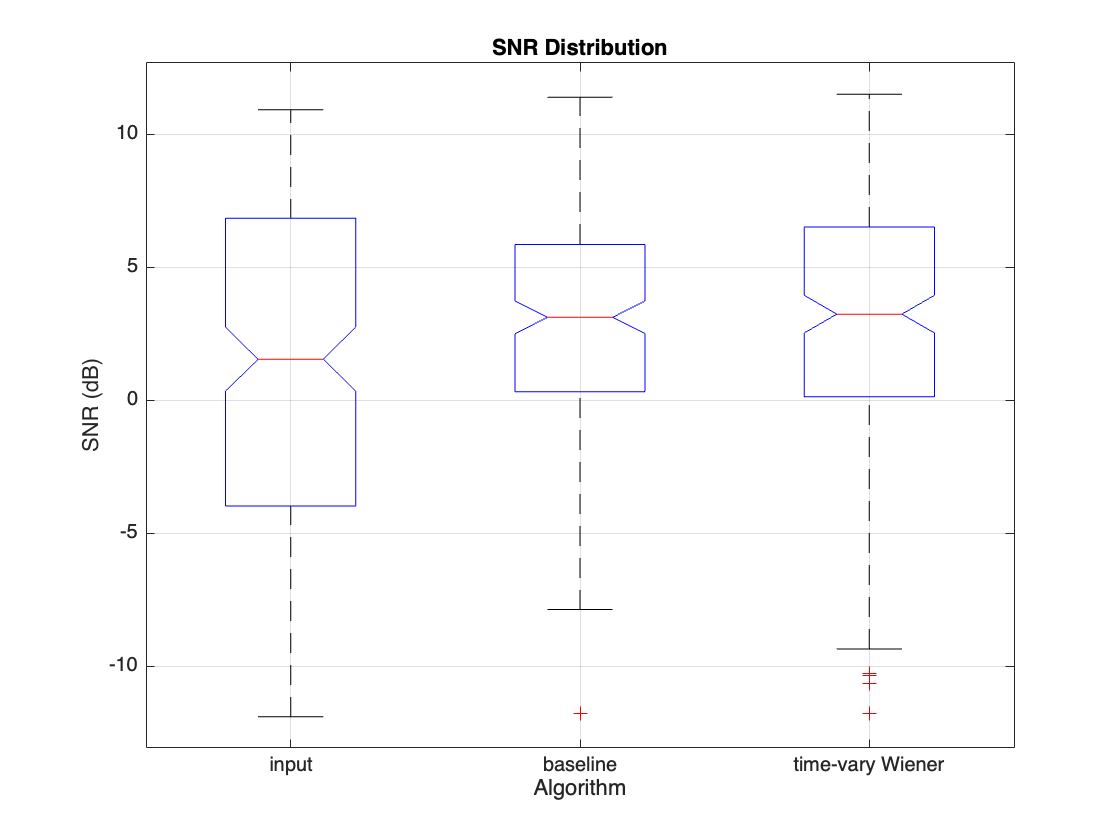

figure;
boxplot([initSnr, finalSnr1, finalSnr2], ...
    'Notch', 'on', ...
    'Labels', ["input", "baseline", "time-vary Wiener"] ...
);
title("SNR Distribution");
xlabel("Algorithm");
ylabel("SNR (dB)");
grid;

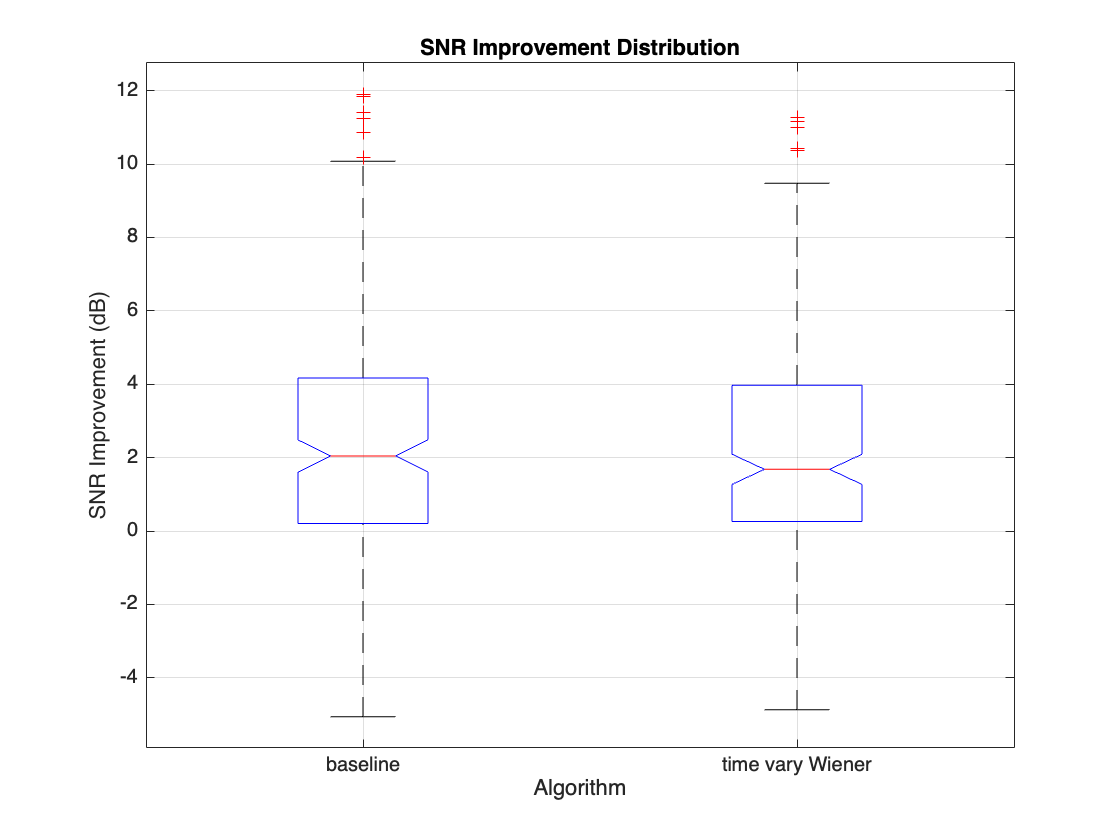

figure;
boxplot([deltaSnr1, deltaSnr2], ...
    'Notch', 'on', ...
    'Labels', ["baseline", "time vary Wiener"] ...
);
title("SNR Improvement Distribution");
xlabel("Algorithm");
ylabel("SNR Improvement (dB)");
grid;

## Profiling

profile clear

nProfileSamples = 10;

profile on


for i = 1:nProfileSamples
    noisyFile = fullfile(devDataPath, devDataFolders(i).name, "noisy.wav");
    cleanFile = fullfile(devDataPath, devDataFolders(i).name, "clean.wav");

    [noisySig, fs] = audioread(noisyFile);
    [cleanSig, fsc] = audioread(cleanFile);

    assert(fs == fsc);
    
    estimSig = denoise(noisySig, fs);
end
profile off

p = profile('info');
profsave(p, "./doc/profile");

The file /./doc/profile/file0.html does not exist.


profile viewer;